# Table of Contents

# How to Run this Script

Before clicking "Run", ensure you have "Contaminated_Data.mat" and "Pure_Data.mat" in your workspace. 

# Target Paper

Y. Li, A. Liu, J. Yin, C. Li and X. Chen, "A Segmentation-Denoising Network for Artifact Removal From Single-Channel EEG," in IEEE Sensors Journal, vol. 23, no. 13, pp. 15115-15127, 1 July 1, 2023, doi: 10.1109/JSEN.2023.3276481.

EOG, EMG, and motion artifact removal from EEG signals are conducted through SDNet, a novel machine learning network for EEG signal denoising. SDNet leverages a segmentation subnetwork to identify noisy parts of the EEG signal and a denoising network to remove artifacts.The motion artifact data was not available, and for simplicity we decided to only include EOG artifact removal in our model. The dataset mentioned in the target paper was open for public use, so we determined this to be our dataset for training/validation/testing. 

# Dataset

To train the SDNet model, semi-simulated data was formed by mixing pre-processed and expert-cleaned EEG signals with intentionally recorded EOG artifacts. 

The EEG and EOG datasets were found at [https://data.mendeley.com/datasets/wb6yvr725d/4](https://data.mendeley.com/datasets/wb6yvr725d/4)

# Data preprocessing Steps

The datasets were then imported into MATLAB to complete the following preprocessing steps. These steps were outlined in the methods section of our target paper and illustrated how noise was added to the clean EEG data:

- Subtract the referenced paper's ground truth EEG from their contaminated EEG provided in the dataset to isolate solely the EOG artifact data. Using the formula stated in our target paper, we were able to extract the pure artifact.

                    To retrieve scaled EOG data according to contamination coefficients:

                    pure artifact =  contaminated EEG - pure EEG 

- Upsampling EEG and EOG data from 200 Hz to 256 Hz

- Standardization of signals

                Subtracting mean value at each timepoint to rereference to the global average

                Dividing each channel by its standard deviation

                Summed 19 channels into one EEG vector. 

We summed each channel into one vector as the paper did not specify whether they used individual channel data        or summed channel data. This step can be reversed if we need more data to increase the dataset by 19 times, as there were 19 channels.

- Separated ground truth EEG into 5sec long segments, and EOG artifact EEG into 2sec long segments

- Extracted the middle second ((0.5-1.5) domain) from the EOG artifact segment to be randomly placed throughout the clean data to simulate random noise

- Divided each ground truth EEG 5sec-long segment into thirds and inserted an artifact segment at a random starting index into that third to produce 5sec-long semisimulated data segments

Because the original article uses three different types of artifact and we are only using one, we did not have enough EOG artifact segments to be able to use all of the ground truth EEG segments (i.e. # of artifact segments < 3 * # of ground truth segments), so the excess were discarded

- Varied the signal-to-noise ratio of the semisimulated segments along a uniform random distribution from -5dB to 5dB according to the equation offered in the target paper's methods section

Our target paper offered a formula describing how variable levels of SNR was mixed into the semisimulated data. We used this formula, solving as needed, shown at the end of this .mlx file

- Separated all of the preprocessed data segments randomly into 80% training, 10% validation, and 10% test datasets

# Start Preprocessing

## EOG import and preprocessing

clear
Contaminated_Data = load('Contaminated_Data.mat');

Pure_Data = load('Pure_Data.mat');

## Turning Contaminated_Data into pure EOG by subtracting the pure data part

fields_Cont = fieldnames(Contaminated_Data);
fields_Pure = fieldnames(Pure_Data);

for i = 1:numel(fields_Cont) 
    current_cont_sim = Contaminated_Data.(fields_Cont{i});
    current_pure_sim = Pure_Data.(fields_Pure{i});
    Contaminated_Data = setfield(Contaminated_Data, fields_Cont{i}, current_cont_sim-current_pure_sim); % removing the pure element in the equation  CONT = Pure + a_ij*VEOG + b_ij*HEOG so that the EOG is the only component left in Contaminated_Data
end

clear current_cont_sim; clear current_pure_sim



## Resampling, Avg subtracting, and Dividing by standard deviation

Where this [paper](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC2666412/) shows that the average referencing technique in EEG is generally referring to the average across all channels at each timepoint (in our case, 1 x numel(sim), not the average of the entire time series of each channel  (where you'd subtract from each channel it's individual average) ) 

**TARGET PAPER: "**To facilitate the synthesis of semisimulated data and neural network training, all the data collected above are resampled to 256 Hz, standardized by subtracting the mean value and dividing by the standard deviation**"**

current_sampling_rate = 200; 
new_sampling_rate = 256;

for i = 1:numel(fields_Cont)
    current_sim = Contaminated_Data.(fields_Cont{i});
    current_sim = resample(double(current_sim'), new_sampling_rate, current_sampling_rate)'; % ' because resample function works along columns not rows
    avg_current_sim_rows = mean(current_sim,1); % along the 1st axis, i.e. rows because you want the avg of the 19 channels at each time point, not the 19 averages over the entire time series. 
    avg_current_sim_rows_duplicated_as_matrix = repmat(avg_current_sim_rows, numel(current_sim(:,1)),1);
    resampled_and_avg_subtracted_current_sim = current_sim - avg_current_sim_rows_duplicated_as_matrix; 
    std_dev_of_each_row = std(resampled_and_avg_subtracted_current_sim')'; % should be 19x1
    std_dev_of_each_row_duplicated_as_matrix = repmat(std_dev_of_each_row,1,numel(resampled_and_avg_subtracted_current_sim(1,:))); % should be 19xnumel(sim_row)
    resampled_and_avg_subtracted_and_std_divided_current_sim = resampled_and_avg_subtracted_current_sim./std_dev_of_each_row_duplicated_as_matrix; % ./ is elementwise division
    Contaminated_Data = setfield(Contaminated_Data, fields_Cont{i}, resampled_and_avg_subtracted_and_std_divided_current_sim); % replacing array in struct with preprocessed array
end

% Repeat for pure

for i = 1:numel(fields_Pure)
    current_sim = Pure_Data.(fields_Pure{i});
    current_sim = resample(double(current_sim'), new_sampling_rate, current_sampling_rate)'; % ' because resample function works along columns not rows
    avg_current_sim_rows = mean(current_sim,1); % along the 1st axis, i.e. rows because you want the avg of the 19 channels at each time point, not the 19 averages over the entire time series
    avg_current_sim_rows_duplicated_as_matrix = repmat(avg_current_sim_rows, numel(current_sim(:,1)),1);
    resampled_and_avg_subtracted_current_sim = current_sim - avg_current_sim_rows_duplicated_as_matrix; 
    std_dev_of_each_row = std(resampled_and_avg_subtracted_current_sim')'; % should be 19x1
    std_dev_of_each_row_duplicated_as_matrix = repmat(std_dev_of_each_row,1,numel(resampled_and_avg_subtracted_current_sim(1,:))); % should be 19xnumel(sim_row)
    resampled_and_avg_subtracted_and_std_divided_current_sim = resampled_and_avg_subtracted_current_sim./std_dev_of_each_row_duplicated_as_matrix; % ./ is elementwise division
    Pure_Data = setfield(Pure_Data, fields_Pure{i}, resampled_and_avg_subtracted_and_std_divided_current_sim); % replacing array in struct with preprocessed array
end

clear std_dev_of_each_row; clear std_dev_of_each_row_duplicated_as_matrix; clear resampled_and_avg_subtracted_and_std_divided_current_sim; clear resampled_and_avg_subtracted_current_sim; clear avg_current_sim_rows_duplicated_as_matrix; clear avg_current_sim_rows; 

## Summing the 19 channels of the contaminated data into 1 summed EEG vector

Contaminated_Data_summed = struct(); % Initializing

for i = 1:numel(fields_Cont)
    current_sim = Contaminated_Data.(fields_Cont{i});
    sum = zeros(1, numel(current_sim(1,:))); 
    for j = 1:numel(current_sim(:,1)) % loop through all the rows == channels
        current_channel = current_sim(j,:);
        sum = sum + current_channel; % adding all the channels together
    end
    Contaminated_Data_summed = setfield(Contaminated_Data_summed, "sim" + num2str(i) + "_con", sum);
end

clear sum; clear i; clear j; clear current_channel; clear current_sim;

## Repeating Summing Process for Pure Data 

Pure_Data_summed = struct(); % Initializing

for i = 1:numel(fields_Pure)
    current_sim = Pure_Data.(fields_Pure{i});
    sum = zeros(1, numel(current_sim(1,:))); 
    for j = 1:numel(current_sim(:,1)) % loop through all the rows == channels
        current_channel = current_sim(j,:);
        sum = sum + current_channel; % adding all the channels together
    end
    Pure_Data_summed = setfield(Pure_Data_summed, "sim" + num2str(i) + "_con", sum);
end

## Variables relevant for extracting segments 

fields_Pure = fieldnames(Pure_Data_summed);
fields_Cont = fieldnames(Contaminated_Data_summed);
sampling_rate = 256;
Pure_segment_length_in_seconds = 5; 
Noise_segment_length_in_seconds = 2;

## Extracting 5sec Segments of ground truth EEG

ground_truth_EEG_segments_uncut = struct(); 

% Could do this both in one for loop but because the segment lengths are different I don't want to confuse myself by keeping track of 2 different length variables

for i = 1:numel(fields_Pure)
     current_sim = Pure_Data_summed.(fields_Pure{i});
     int_length_current_sim = int16(numel(current_sim(1,:))); % one channel now
     int_segment_length = int16(Pure_segment_length_in_seconds*sampling_rate); % because we want 5sec long segments at 256 Hz-- 1280
     num_segments_current_sim = idivide(int_length_current_sim, int_segment_length);
     stopping_index = num_segments_current_sim * int_segment_length; % num * 1280
     random_starting_index = randi(int_length_current_sim - stopping_index, 1);

     % Now a loop to add each segment to my final dataset struct
     segment_start = random_starting_index; % initializing for loop
     for j = 1:(num_segments_current_sim)
        segment_end = segment_start + int_segment_length;
        ground_truth_EEG_segments_uncut= setfield(ground_truth_EEG_segments_uncut, "ground_truth_segment" + num2str(i) + "_" + num2str(j), current_sim(segment_start:segment_end - 1)); % Subtracting 1 from segment end because start:end is inclusive and I want 1280-long vector not 1281
        segment_start = segment_end; 
     end
end

clear i; clear j; clear current_sim; clear segment_start; clear segment_end; clear random starting_index;
clear Pure_Data; clear Pure_Data_summed; clear fields_Pure;

## Extracting 2sec long segments of noise EEG and pulling the innermost 1sec long interval

EOG_artifact_EEG_segments = struct();
int_segment_length = int16(Noise_segment_length_in_seconds*sampling_rate); % because we want 2sec long segments at 256 Hz, 512

for i = 1:numel(fields_Cont)
     current_sim = Contaminated_Data_summed.(fields_Cont{i});
     int_length_current_sim = int16(numel(current_sim(1,:))); 
     num_segments_current_sim = idivide(int_length_current_sim, int_segment_length);
     stopping_index = num_segments_current_sim * int_segment_length;
     random_starting_index = randi(int_length_current_sim - stopping_index, 1);

     % Now a loop to add each segment to my final dataset struct
     segment_start = random_starting_index; % initializing for loop
     for j = 1:num_segments_current_sim
        segment_end = segment_start + int_segment_length;
        EOG_artifact_EEG_segments = setfield(EOG_artifact_EEG_segments, "EOG_segment" + num2str(i) + "_" + num2str(j), current_sim(segment_start + 128: segment_start + 383)); % Because the paper extracts the domain (0.5s - 1.5s) from the 2s long segment. 0.5*256 = 128, 1.5*256 = 384. Subtract one so that you don't get 257 since start:finish is inclusive
        segment_start = segment_end; 
     end
end

## Shuffling order of noise segments to prevent a pattern 

EOG_eeg_fields = fieldnames(EOG_artifact_EEG_segments);
random_permutation_array = randperm(numel(EOG_eeg_fields));
EOG_artifact_EEG_segments_permuted = struct(); %init

for i = 1:numel(EOG_eeg_fields)
    random_artifact = EOG_artifact_EEG_segments.(EOG_eeg_fields{random_permutation_array(i)});
    EOG_artifact_EEG_segments_permuted = setfield(EOG_artifact_EEG_segments_permuted, "EOG_segment_" + num2str(i), random_artifact);
end

clear i; clear j; clear current_sim; clear segment_start; clear segment_end; clear random starting_index; clear stopping_index; 
clear Contaminated_Data; clear Contaminated_Data_summed; clear fields_Cont; clear EOG_artifact_EEG_segments;

## Taking a number of ground truth segments randomly from the data to correspond to the  maximum divisbly by 3 number of noise eeg segments that will be needed to do the complete semisimulated dataset

ground_truth_EEG_segments = struct(); 

clean_eeg_fields = fieldnames(ground_truth_EEG_segments_uncut);

EOG_eeg_fields = fieldnames(EOG_artifact_EEG_segments_permuted);
random_indices = randperm(numel(clean_eeg_fields),idivide(int16(numel(EOG_eeg_fields)),int16(3))); %3 because there are 3 artifact segments per semisimulated data segment
  
for i = random_indices
    ground_truth_EEG_segments = setfield(ground_truth_EEG_segments, clean_eeg_fields{i}, ground_truth_EEG_segments_uncut.(clean_eeg_fields{i}));
end

clear ground_truth_EEG_segments_uncut; clear clean_eeg_fields;

## Removing the superfluous EOG segments that won't be used

%% This is due to the fact that the number of EOG segments is not necessarily a number divisible by 3
num_EOG_segments = numel(EOG_eeg_fields);
num_fields_to_remove = mod(num_EOG_segments, 3);
for i = 0:num_fields_to_remove - 1 % subtract 1 because you start w/ "end" 
    EOG_artifact_EEG_segments_permuted = rmfield(EOG_artifact_EEG_segments_permuted, EOG_eeg_fields{end-i}); % This will always remove the last x number of fields. This is not a problem because the fields have already been randomized in order and you're only ever at most removing 2 fields
end

clear i; 

## Putting EOG into thirds of the Clean data

num_artifacts_inserting = 3; 
length_clean_eeg = Pure_segment_length_in_seconds*sampling_rate;
first_stopping_index = idivide(int16(length_clean_eeg), int16(num_artifacts_inserting));
second_stopping_index = first_stopping_index*2;

ground_truth_fields = fieldnames(ground_truth_EEG_segments);
third_stopping_index= length_clean_eeg; % 1280-- this means the third segment will be a little longer (2 samples) than the first two 
stopping_indices = struct('first', first_stopping_index, 'second', second_stopping_index, 'third', third_stopping_index);
stopping_indices_fields = fieldnames(stopping_indices);

semisimulated_data = struct(); %initializing
SNR_range = [-5, 5]; % as provided in the target paper

EOG_segment_length = numel(EOG_artifact_EEG_segments_permuted.(EOG_eeg_fields{1})(1,:));

last_index = 1; % initializing
for i = 1:numel(ground_truth_fields)
     current_clean_segment = ground_truth_EEG_segments.(ground_truth_fields{i});
     segment_placeholder = zeros(1, length_clean_eeg);
     final_prior_segment_index = 1;
     semisimulated_noise_indices = struct(); % initializing
     for j = last_index:last_index + 2 % this ensures you don't hit the same index over; starts with 1, 2,3 then 1+3 = 4 so goes 4, 5, 6
         
         current_noise_segment = EOG_artifact_EEG_segments_permuted.(EOG_eeg_fields{j});
          
         index_stopping_indices_struct = mod(j,3); 
         if index_stopping_indices_struct == 0
             index_stopping_indices_struct = 3;
         end
         
         random_starting_index = randi([final_prior_segment_index, stopping_indices.(stopping_indices_fields{index_stopping_indices_struct}) - EOG_segment_length], 1); % on each loop the stopping index iterates. The starting index is always 256 samples away from the stopping index, ensuring no clipping
         semisimulated_noise_indices = setfield(semisimulated_noise_indices, "noise_" + num2str(i) + "_" + num2str(index_stopping_indices_struct) + "_indices", [ random_starting_index, random_starting_index + EOG_segment_length]);
         
         final_prior_segment_index = stopping_indices.(stopping_indices_fields{index_stopping_indices_struct}); % reset so that the next round's minimum random starting index is the beginning of the segment 

         zero_padded_noise_segment = zeros(1,length_clean_eeg);
         zero_padded_noise_segment(random_starting_index:random_starting_index + EOG_segment_length - 1) = current_noise_segment; % -1 to keep the sides both 256 long
         segment_placeholder = segment_placeholder + zero_padded_noise_segment;
     end
     lambda = randomize_SNR(segment_placeholder, current_clean_segment, SNR_range); 
     semisimulated_segment = (lambda * segment_placeholder) + current_clean_segment;
     last_index = last_index + 3;
     semisimulated_data = setfield(semisimulated_data, "segment_" + num2str(i) , (struct("semisimulated_segment_" + num2str(i), semisimulated_segment, "semisimulated_segment_" + num2str(i) + "_noise_indices", semisimulated_noise_indices, "ground_truth_segment_" + num2str(i), current_clean_segment)));
end



## Plotting a ground truth and paired semisimulated signal for demonstrative purposes

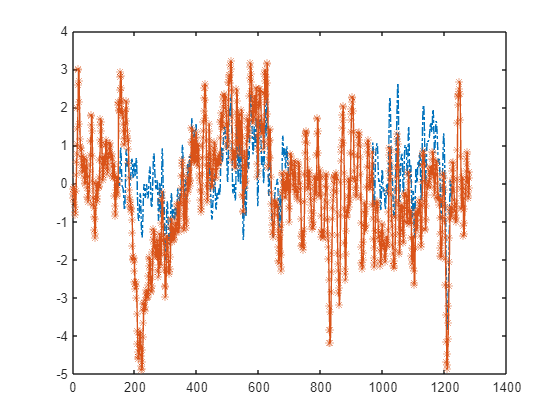

close;plot(1:1280,semisimulated_data.segment_1.ground_truth_segment_1,'-. '); hold on; plot(1:1280,semisimulated_data.segment_1.semisimulated_segment_1,'-*');

## Saving data

save("semisimulated_data.mat", "semisimulated_data");

# Separating Data into Training, Validation, and Test sets

clear
clc
close all

## Making Sets of correct length and getting masks

% Randomly Generate Values into train, validation, test

train= 0.8;
val= 0.1;
test=0.1;

data_struct = load("semisimulated_data.mat");
data_struct_names = fieldnames(data_struct.semisimulated_data);


len= length(data_struct_names); % 266

trainNum= round(len*train); % making ints out of the proportion of segments allocated to each section
valNum= floor(len*val);
testNum= round(len*test);


random_mask= randperm(len,len); % creating a mask of randomly permuted indices
trainInd= random_mask(1:trainNum); 
valInd= random_mask(trainNum+1: trainNum+valNum);
testInd= random_mask(trainNum+valNum+1:end);


## Saving data into trainSet, valSet, testSet .mat files

trainSet= cell(4,length(trainInd));
valSet= cell(4, length(valInd));
testSet= cell(4,length(testInd));



% Save train set values
for i=1:length(trainInd)
    segment = data_struct.semisimulated_data.(data_struct_names{trainInd(i)}); % using trainInd to index the fieldname== selects random segment from the struct
    segment_fieldname = fieldnames(segment);
    trainSet{1,i}= segment_fieldname{1}; % becuase 1st field is the semisimulated array
    trainSet{2,i}= segment.(segment_fieldname{1});
    trainSet{3,i}= segment_fieldname{3}; % because 2nd field is the indices, 3rd field is the grount truth
    trainSet{4,i}= segment.(segment_fieldname{3});

end

% Save validation set values
for j=1:length(valInd)
    segment = data_struct.semisimulated_data.(data_struct_names{valInd(j)}); % using trainInd to index the fieldname== selects random segment from the struct
    segment_fieldname = fieldnames(segment);
    valSet{1,j}= segment_fieldname{1}; % becuase 1st field is the semisimulated array
    valSet{2,j}= segment.(segment_fieldname{1});
    valSet{3,j}= segment_fieldname{3}; % because 2nd field is the indices, 3rd field is the grount truth
    valSet{4,j}= segment.(segment_fieldname{3});   
   
end

% Set test set values
for k=1:length(testInd)
    segment = data_struct.semisimulated_data.(data_struct_names{testInd(k)}); % using trainInd to index the fieldname== selects random segment from the struct
    segment_fieldname = fieldnames(segment);
    testSet{1,k}= segment_fieldname{1}; % becuase 1st field is the semisimulated array
    testSet{2,k}= segment.(segment_fieldname{1});
    testSet{3,k}= segment_fieldname{3}; % because 2nd field is the indices, 3rd field is the grount truth
    testSet{4,k}= segment.(segment_fieldname{3});   
end

save trainSet.mat trainSet
save validationSet.mat valSet
save testSet.mat testSet

# `Obtaining objective assessment results from the state of the art methods`

% Savitzky- Golay filtering on data
clear
clc
close all

SData= load("testSet.mat");
testSet= SData.testSet;

order= 3;
frameLen= 7;


for i= 1:length(testSet)
    sgf(i,:)= sgolayfilt(testSet{2,i},order,frameLen);
end

for j=1:length(testSet)
    groundTruth{j,:}= testSet{4,j};
end

for k=1:size(sgf,1)
    c= corrcoef(sgf(k,:),groundTruth{k});
    corr(k)= c(2,1);
    rmsNum= sum((sgf(k,:)-groundTruth{k}).^2 );
    rmsDen= sum(sgf(k,:).^2);
    rrmse(k)= sqrt(rmsNum/rmsDen);
    snrNum= sum(sgf(k,1:end-1).^2);
    snrDen= sum((sgf(k,1:end-1)-groundTruth{k}(1:end-1)).^2 );
    snr(k)= 10*log10(snrNum/snrDen);

end

## Objective Assessment Results

CC= mean(corr)*100;
SNR= mean(snr);
RRMSE= mean(rrmse);
clearvars -except CC SNR RRMSE
Thanks_Arian = "  :)  ";


# Starting work on the target paper's model

Because the preprocessing steps were so extensive, we have not started writing building the model. We have, however, confirmed that we will be builidng the segmentation network from scratch and using the target paper's code for the denoising network. That code is found at this github: [SDNet/network at main · yuqingli1/SDNet (github.com)](https://github.com/yuqingli1/SDNet/tree/main). 

# `Functions`

function lambda = randomize_SNR(noise_segment_placeholder, clean_EEG_segment, SNR_range)
%RANDOMIZE_SNR:  produces a lambda value for scaling of noise corresponding to a random SNR between the range provided using the uniform random distribution
%   
%   noise_segment_placeholder - A row vector of double representing the noise in the EEG signal. May include many indices with 0 as a value
%
%   clean_EEG_segment - A row vector of double representing the non-noisy, ground truth EEG signal.
%
%   SNR_range - A 1x2 matrix representing (1,1) the lower bound of the SNR range and (1,2) the upper bound 
%
%   lambda = randomize_SNR(noise_segment_placeholder, clean_EEG_segment)
%
% See also RAND
   
    SNR_lower_bound = SNR_range(1);
    SNR_upper_bound = SNR_range(2);
    
    SNR = SNR_lower_bound + (SNR_upper_bound - SNR_lower_bound)*rand(1); % to randomly distribute the values along this interval
    
    % initializing 
    lambda = NaN;
    sum_ground_truth = 0;
    sum_noise = 0;
    
    Z = noise_segment_placeholder;
    Y = clean_EEG_segment;
    
    for i = 1:1280
        sum_noise = sum_noise + (Z(i)^2);
        sum_ground_truth = sum_ground_truth + (Y(i)^2);
    end
    
    lambda = sqrt ( 10^(-SNR/10)* ((sum_ground_truth) / (sum_noise))  );
    
    clear Z; clear Y; clear SNR_lower_bound; clear SNR_upper_bound; clear SNR;

end


## Derivation of Lambda

`Contamined EEG signal generated by linearly mixing artifacts with clean EEG signal: `


$$$X = Y+\lambda Z$$$


`where X: contaminated EEG signal`

`      Y: clean EEG signal, `

`      Z: artifacts, `

             $$\lambda$
$`  is a coefficient controlling signal-to-noise ratio`

`SNR in paper ranged from [-5,5``] dB using uniform random distribution`


$$$SNR(dB) = 10 \log_{10}{\frac{\sum_{i=0}^{N}{y_i^2}}{\sum_{i=0}^{N}{(\lambda \cdot z_i)^2}}}$

$\frac{SNR}{10}=\log_{10}{\frac{\sum_{i=0}^{N}{y_i^2}}{\sum_{i=0}^{N}{(\lambda \cdot z_i)^2}}}$

$10^\frac{SNR}{10} = {\frac{\sum_{i=0}^{N}{y_i^2}}{\sum_{i=0}^{N}{(\lambda \cdot z_i)^2}}}$

$10^\frac{SNR}{10} = {\frac{\sum_{i=0}^{N}{y_i^2}}{\lambda^2\sum_{i=0}^{N}{z_i^2}}}$

$\lambda^2 = 10^\frac{10}{SNR}{\frac{\sum_{i=0}^{N}{y_i^2}}{\sum_{i=0}^{N}{z_i^2}}}$

$ \lambda = \sqrt{10^\frac{10}{SNR}{\frac{\sum_{i=0}^{N}{y_i^2}}{\sum_{i=0}^{N}{z_i^2}}}}$
$$
